# Run the optimisation.

Prepare the result cache.

% Get the creation date.
CreationDate = datetime();

% Get the directory.
dir = 'data/results/optimisation/';
if ~exist(dir, "dir")
    mkdir(dir);
end

% Get the result file.
result_file = [dir, datestr(CreationDate, 'yyyy-mm-dd_HH-MM-SS'), '.mat'];

Initialize the OptProblem

StartDate = datetime('2021-01-01')

StartDate = datetime
   01-Jan-2021


MaxVaccinesPerDay = (7.4e6 + 1.8e6 + 14.9e6) / 365

MaxVaccinesPerDay = 6.6027e+04

Lethality = [0.00022274,0.00022274,0.00022274,0.00022274,0.00022274,0.00221398,0.01351613,0.134212];
P = lib.classes.OptProblem(...
    'CostFunc', 'total_deaths', ...
    'CostFuncParams', Lethality, ...
    'VaccineEfficacy', 0.95, ...
    'StartDate', StartDate, ...
    'MaxVaccinesPerDay', MaxVaccinesPerDay, ...
    'Tau', 14, ...
    'ReprEff', 1.15, ...
    'Steps', 365 ...
);

Serialize the OptProblem

OptProblemDescription = P.toStruct();
save(result_file, "OptProblemDescription", "CreationDate");

## No Vaccination.

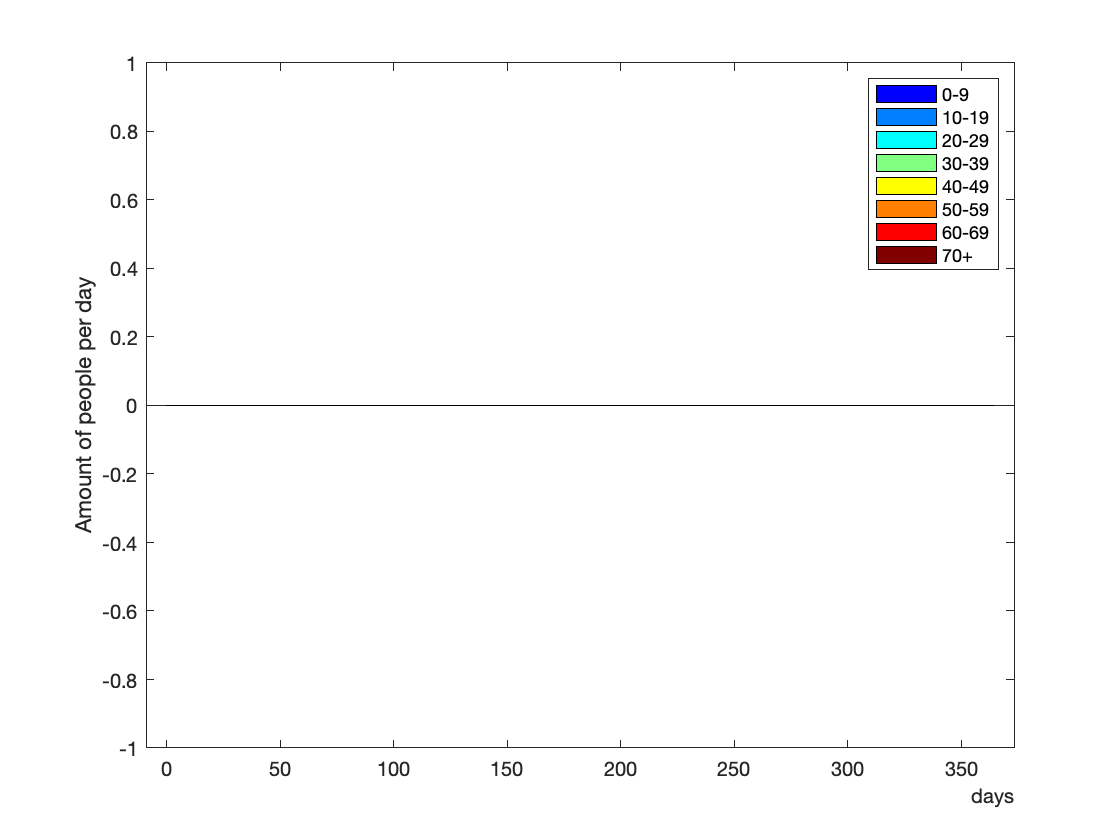

[empty_VS, empty_score] = P.runEmptyStrategy();
figure;
empty_VS.plotArea();

empty_MR = P.getResult(empty_VS);
empty_score

empty_score = 6.9438e+04

Serialize the result.

empty_results = struct( ...
    'VaccinationStrategy', empty_VS.toStruct(), ...
    'ModelResult', empty_MR.toStruct(), ...
    'CostFuncValue', empty_score, ...
    'Name', 'No Vaccination' ...
);
save(result_file, "empty_results", "-append");

## Genetic Algoritm.

-> Creating the optimisation problem parameters...
  -> Creating the optimisation problem options...
    -> Creating the population matrix...
      -> Creating 10 best order strategies...
        -> Getting all permutations of 8 groups...
        -> Getting all 40320 order strategies...
        -> Compute the scores of the 40320 order strategies...
        -> Order the 40320 order strategies by their score...
      -> Creating 500 random order strategies...
      -> Creating 290 random full strategies...
         800        2920

[X]___ Optimisation options have been created!___________________________________
  ga options:

   Set properties:
             ConstraintTolerance: 1.0000e-03
                    CrossoverFcn: {@crossoverintermediate  [1]}
                         Display: 'final'
                      EliteCount: 40
                    FitnessLimit: 0
               FunctionTolerance: 1.0000e-04
  

Optimization terminated: maximum number of generations exceeded.


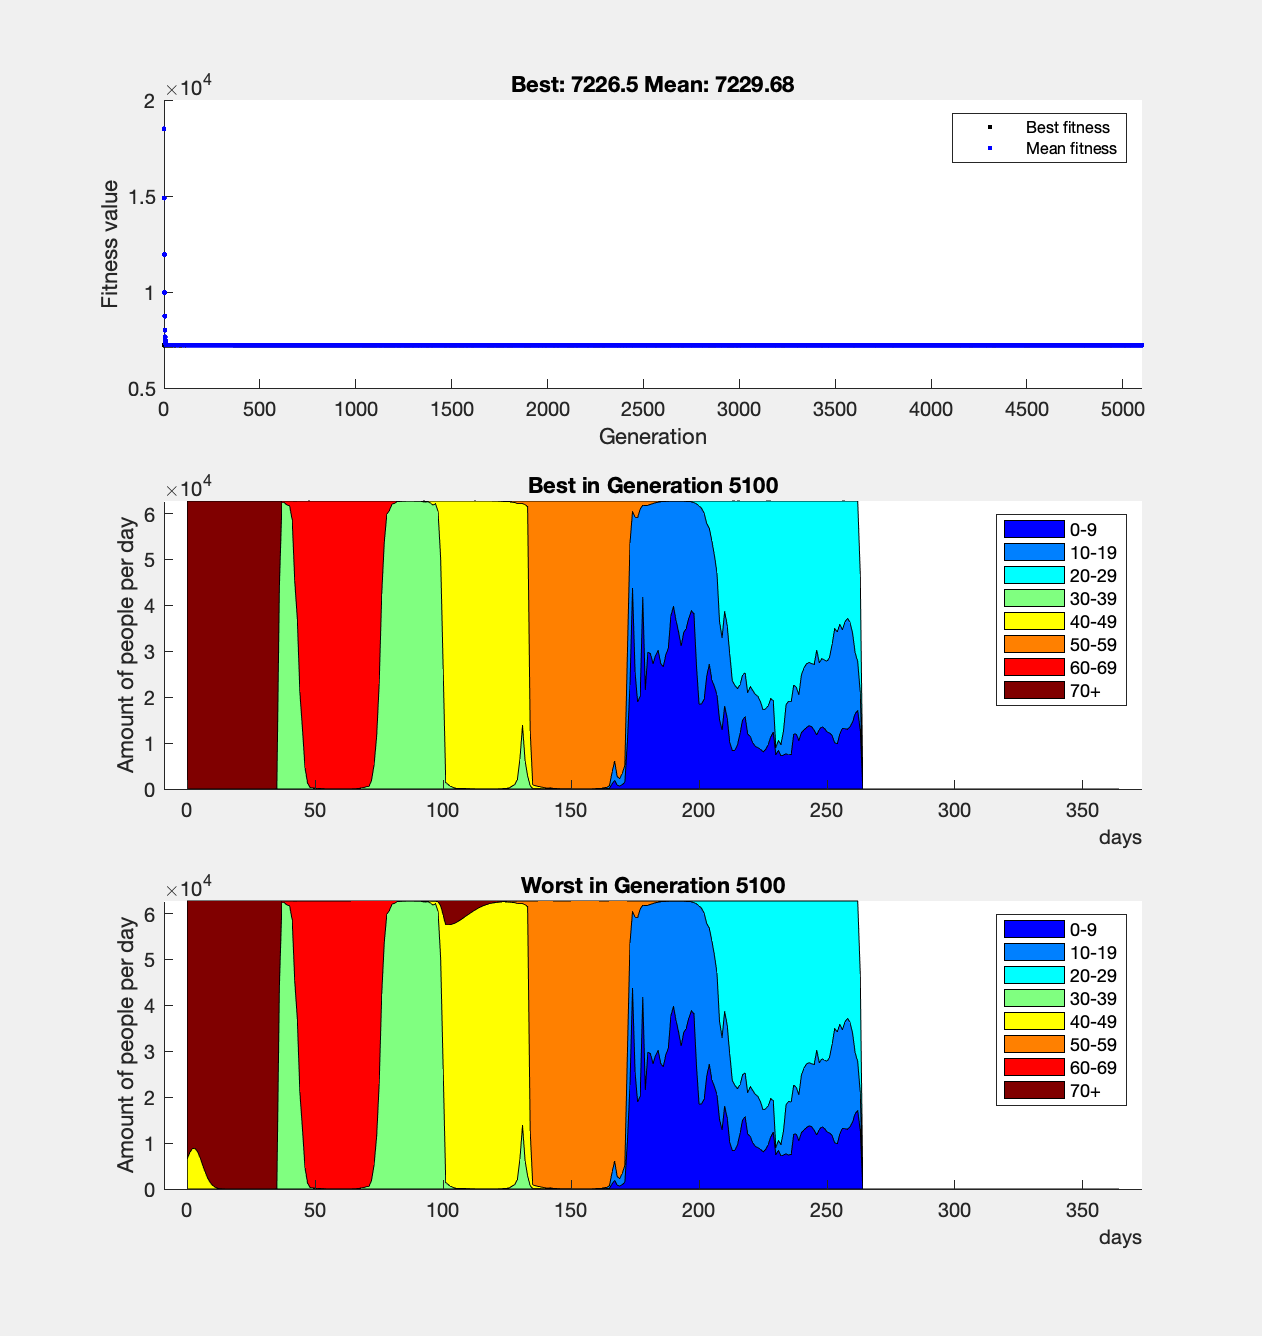

[ga_VS, ga_score] = P.runGeneticAlgorithm( ...
    'MaxGenerations', 5100, ...
    'MaxStallGenerations', inf, ... 
    'InitBestOrderStrategies', 10, ...
    'InitRandomOrderStrategies', 500, ...
    'InitRandomFullStrategies', 290 ...
);

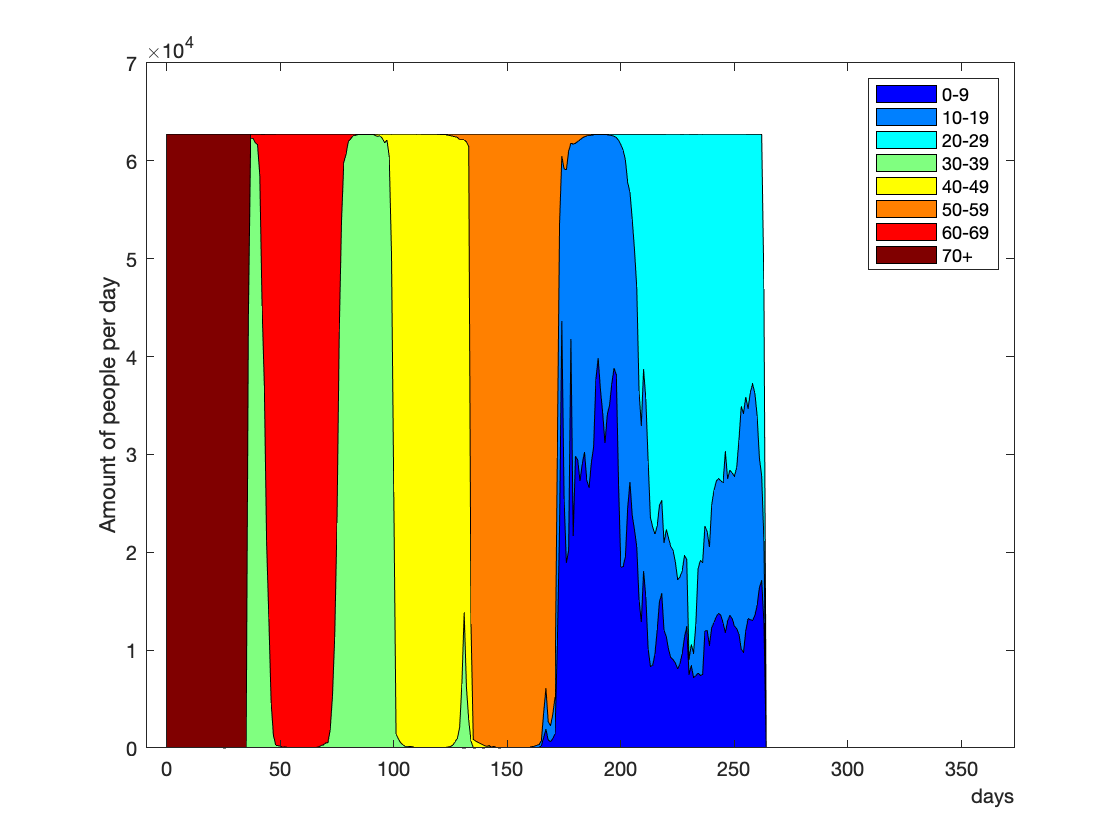

figure;
ga_VS.plotArea();

ga_MR = P.getResult(ga_VS);
ga_score

ga_score = 7.2265e+03

Serialize the result.

ga_results = struct( ...
    'VaccinationStrategy', ga_VS.toStruct(), ...
    'ModelResult', ga_MR.toStruct(), ...
    'CostFuncValue', ga_score, ...
    'Name', 'Genetic Algoritm' ...
);
save(result_file, "ga_results", "-append");

## Differential Evolution.

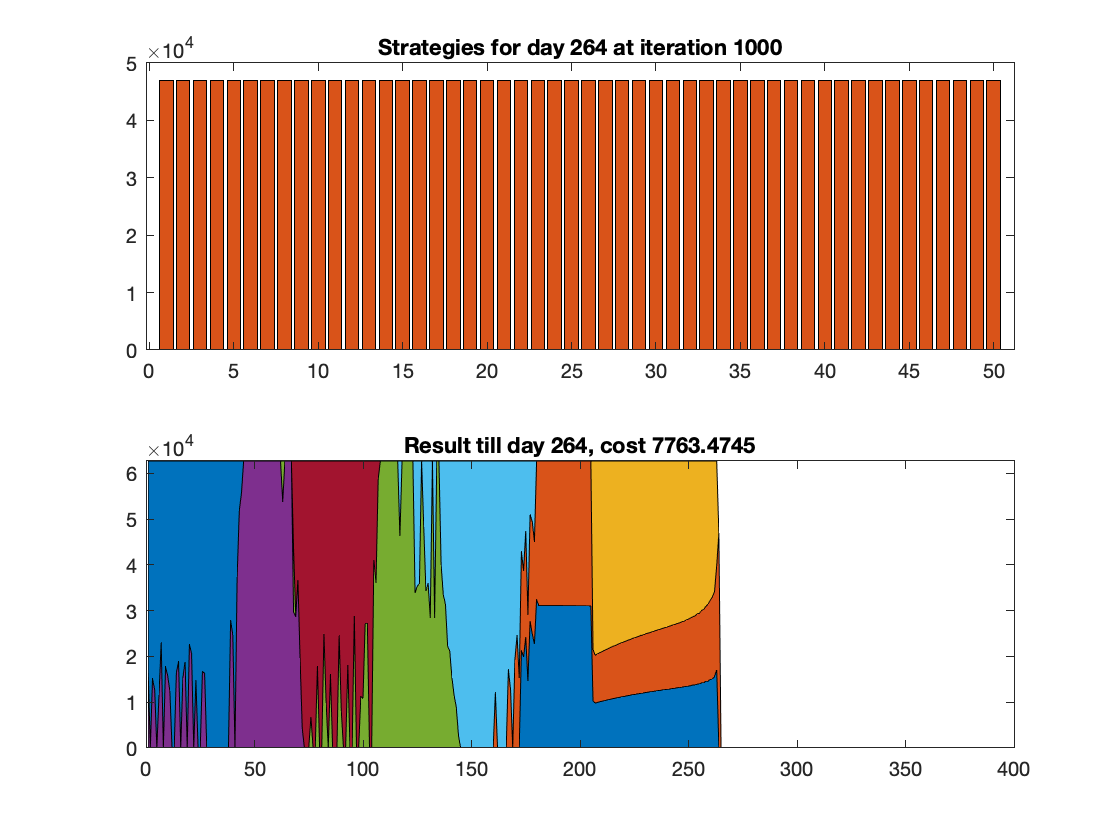

[de_VS, de_score] = P.runDifferentialEvolution( ...
    'Iterations', 1000 , ...
    'PopulationSize', 50 ...
);

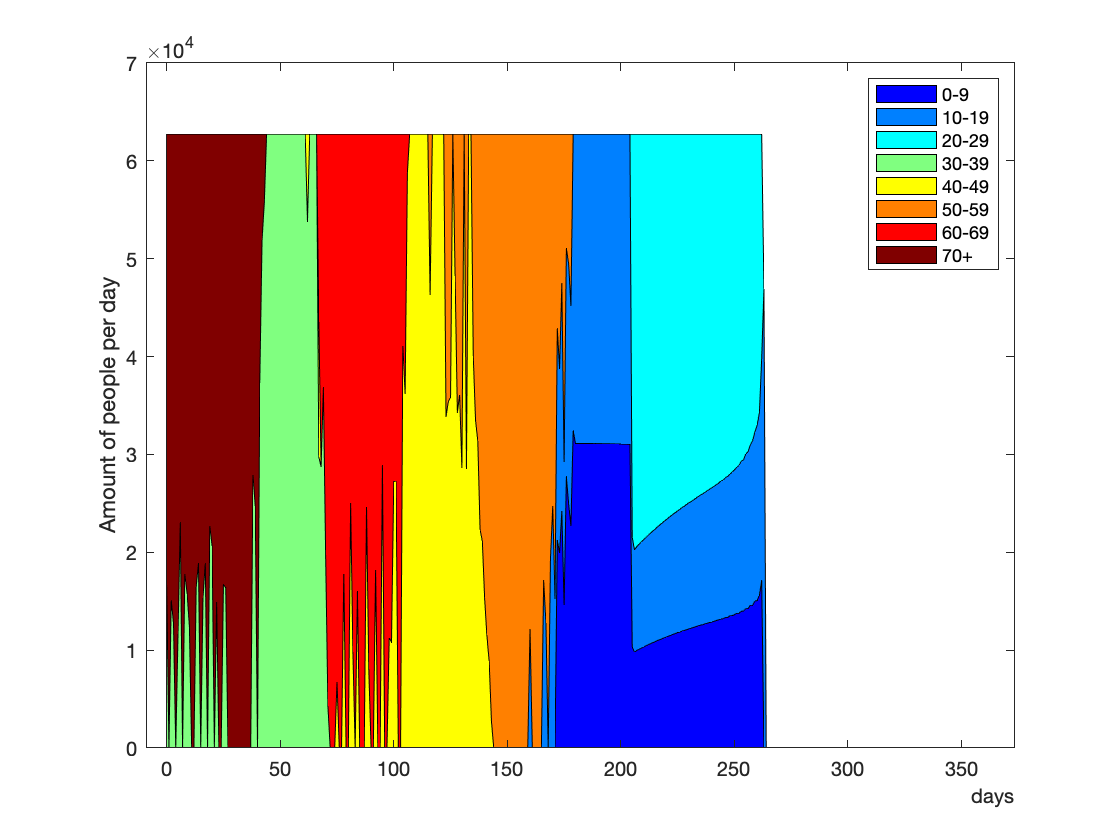

figure;
de_VS.plotArea();

de_MR = P.getResult(de_VS);
de_score

de_score = 7.7635e+03

Serialize the result.

de_results = struct( ...
    'VaccinationStrategy', de_VS.toStruct(), ...
    'ModelResult', de_MR.toStruct(), ...
    'CostFuncValue', de_score, ...
    'Name', 'Differential Evolution' ...
);
save(result_file, "de_results", "-append");

## Best Ordered Strategy.

[ord_best_VS, ord_best_score] = P.runBestOrder();

=> Getting the best order strategy.
        -> Getting all permutations of 8 groups...
        -> Getting all 40320 order strategies...
        -> Compute the scores of the 40320 order strategies...
        -> Order the 40320 order strategies by their score...


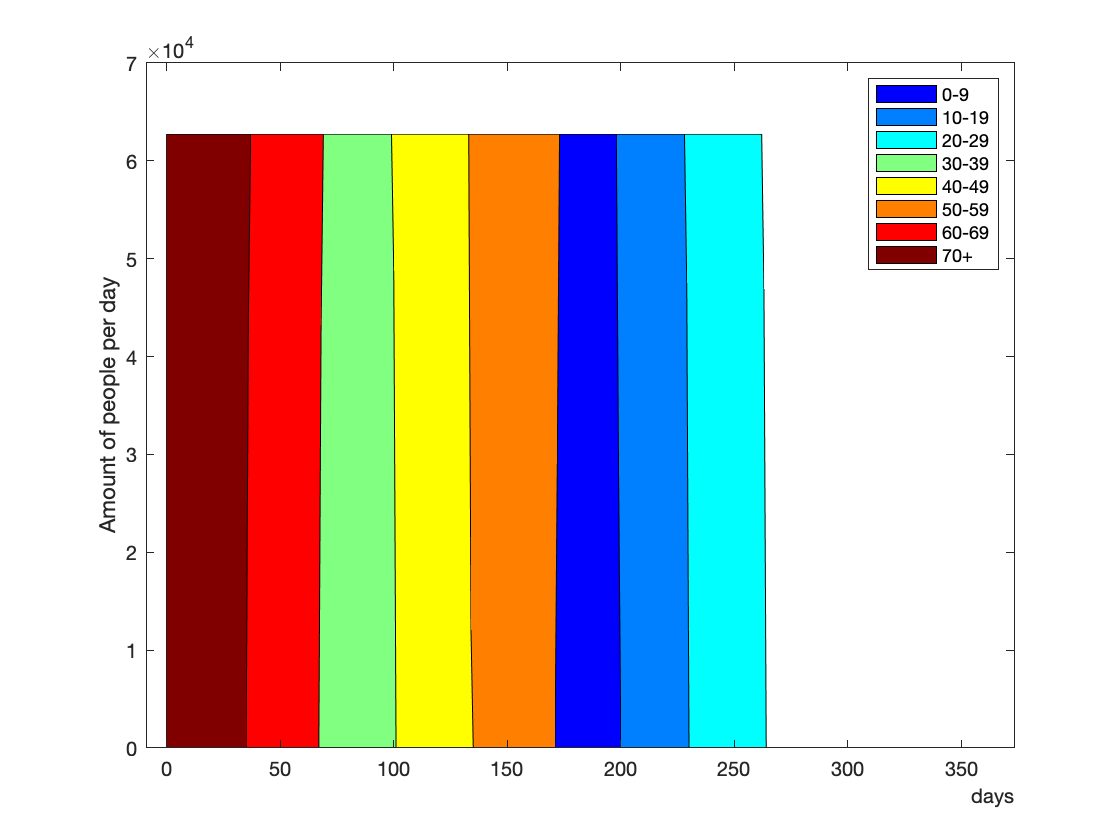

figure;
ord_best_VS.plotArea();

ord_best_MR = P.getResult(ord_best_VS);
ord_best_score

ord_best_score = 7.2357e+03

Serialize the result.

ord_best_results = struct( ...
    'VaccinationStrategy', ord_best_VS.toStruct(), ...
    'ModelResult', ord_best_MR.toStruct(), ...
    'CostFuncValue', ord_best_score, ...
    'Name', 'Best Order' ...
);
save(result_file, "ord_best_results", "-append");

## Decreasing Order Strategy.

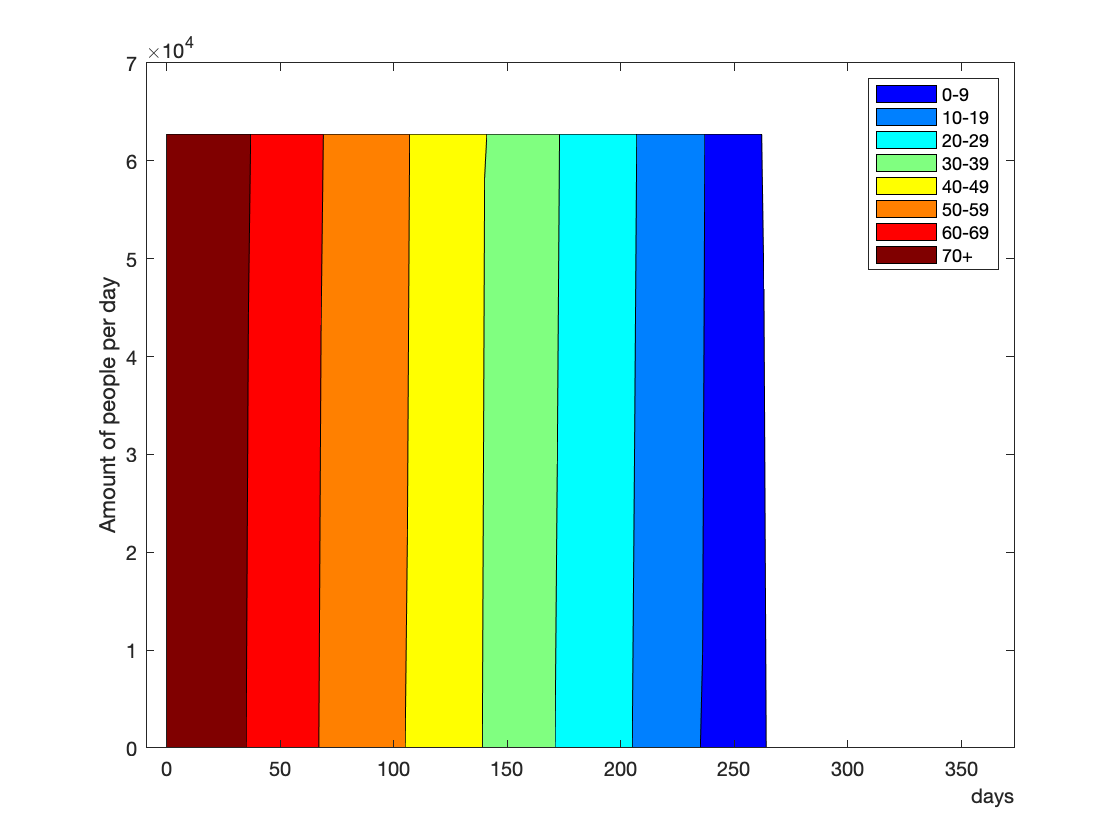

[ord_desc_VS, ord_desc_score] = P.runOrderStrategy(flip(1:P.m));
figure;
ord_desc_VS.plotArea();

ord_desc_MR = P.getResult(ord_desc_VS);
ord_desc_score

ord_desc_score = 7.3648e+03

Serialize the result.

ord_desc_results = struct( ...
    'VaccinationStrategy', ord_desc_VS.toStruct(), ...
    'ModelResult', ord_desc_MR.toStruct(), ...
    'CostFuncValue', ord_desc_score, ...
    'Name', 'Decreasing Order' ...
);
save(result_file, "ord_desc_results", "-append");

## Random Order Strategy.

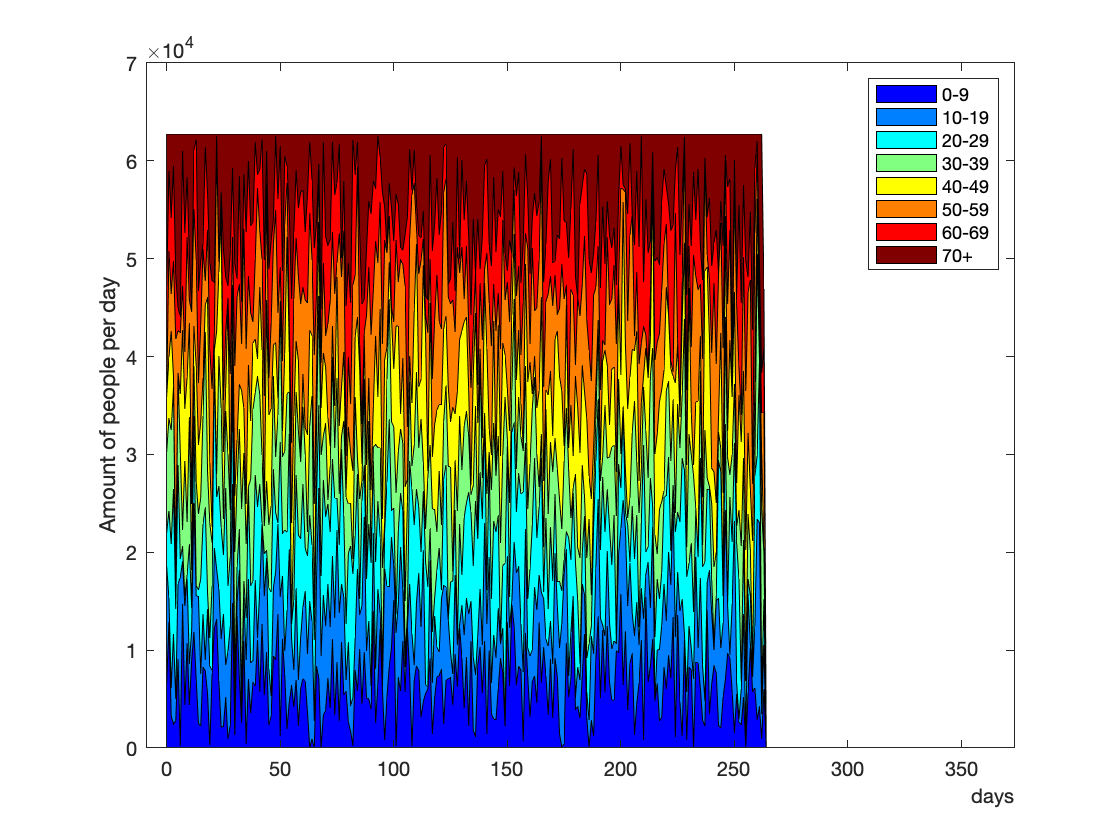

[rand_VS, rand_score] = P.runRandomStrategy();
figure;
rand_VS.plotArea();

rand_MR = P.getResult(rand_VS);
rand_score

rand_score = 1.7810e+04

Serialize the result.

rand_results = struct( ...
    'VaccinationStrategy', rand_VS.toStruct(), ...
    'ModelResult', rand_MR.toStruct(), ...
    'CostFuncValue', rand_score, ...
    'Name', 'Random' ...
);
save(result_file, "rand_results", "-append");

## Uniform Strategy.

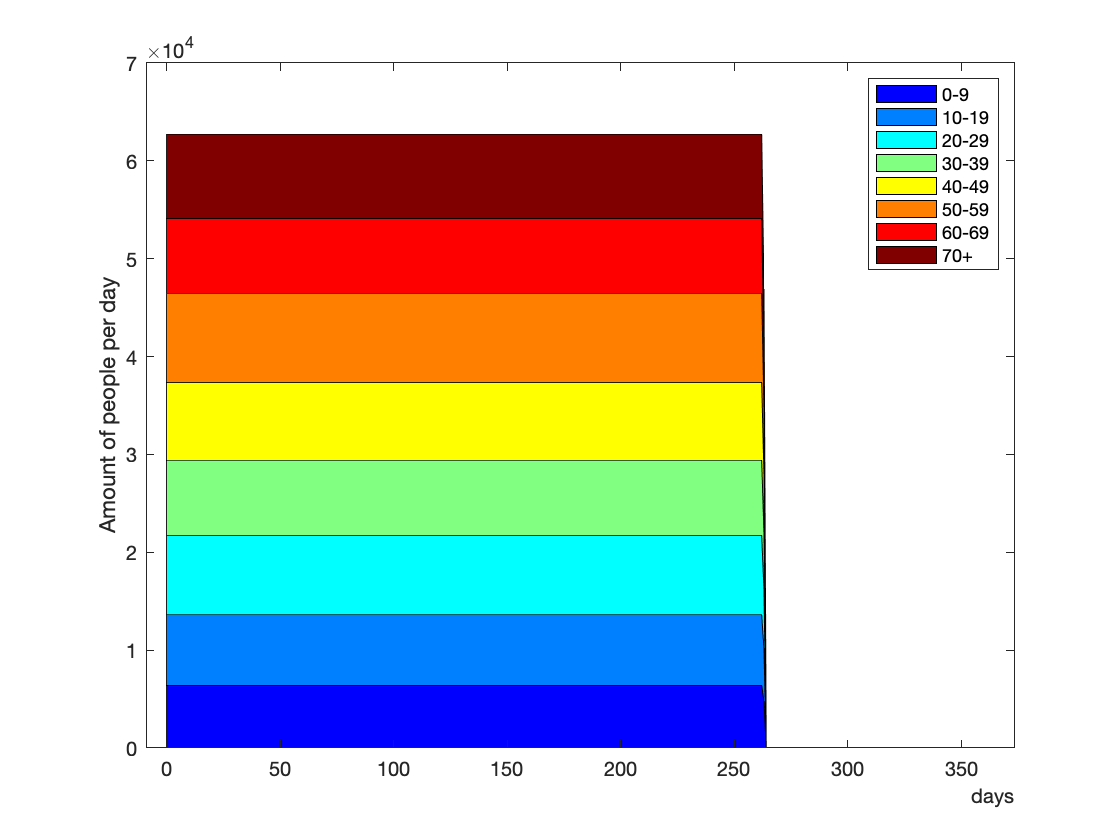

[unif_VS, unif_score] = P.runUniformStrategy();
figure;
unif_VS.plotArea();

unif_MR = P.getResult(unif_VS);
unif_score

unif_score = 1.7968e+04

Serialize the result.

unif_results = struct( ...
    'VaccinationStrategy', unif_VS.toStruct(), ...
    'ModelResult', unif_MR.toStruct(), ...
    'CostFuncValue', unif_score, ...
    'Name', 'Uniform' ...
);
save(result_file, "unif_results", "-append");